# Generalized System Response

Example 3: Matlab Solution. Find system response using Laplace. Uses the symbolic toolbox function `ilaplace` to solve:


$$x(t) = \mathcal{L}\left\{ {{{(s{\mathbf{I}} - {\mathbf{A}})}^{ - 1}}{{\mathbf{x}}_0}
+ {{(s{\mathbf{I}} - {\mathbf{A}})}^{ - 1}}{\mathbf{B}}U(s)} \right\}$$


## Define state-space equations

A = [-3 -2
1 0]

A =     -3    -2
     1     0


B = [1
0]

B =      1
     0


x0 = [1 1]';

syms s t
Us = 1/s

$$Us = \frac{1}{s}$$

Xs = inv(s*eye(2) - A)*x0 + inv(s*eye(2) - A)*B*Us

$$Xs = \left(\begin{array}{c} \frac{s}{s^{2}+3\,s+2}-\frac{1}{s^{2}+3\,s+2}\\ \frac{1}{s^{2}+3\,s+2}+\frac{s+3}{s^{2}+3\,s+2}+\frac{1}{s\,\left(s^{2}+3\,s+2\right)} \end{array}\right)$$

x = ilaplace(Xs)

$$x = \left(\begin{array}{c} 3\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t}\\ 2\,{\mathrm{e}}^{-t}-\frac{3\,{\mathrm{e}}^{-2\,t}}{2}+\frac{1}{2} \end{array}\right)$$

## Print it nicely

For m-file only!

pretty(x)

/   exp(-2 t) 3 - 2 exp(-t)   \
|                             |
|             exp(-2 t) 3   1 |
| 2 exp(-t) - ----------- + - |
\                  2        2 /



## Plot response

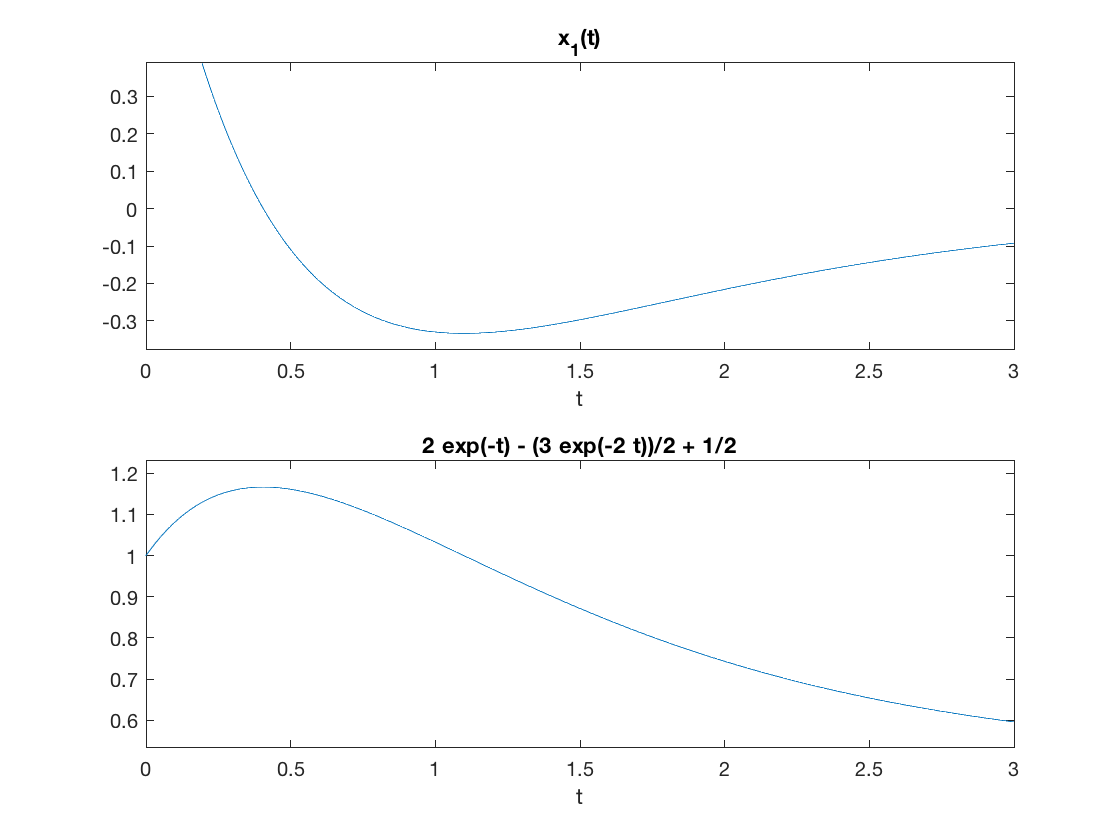

subplot(211)
ezplot(x(1),[0,3])
title('x_1(t)')
subplot(212)
title('x_2(t)')
ezplot(x(2),[0,3])